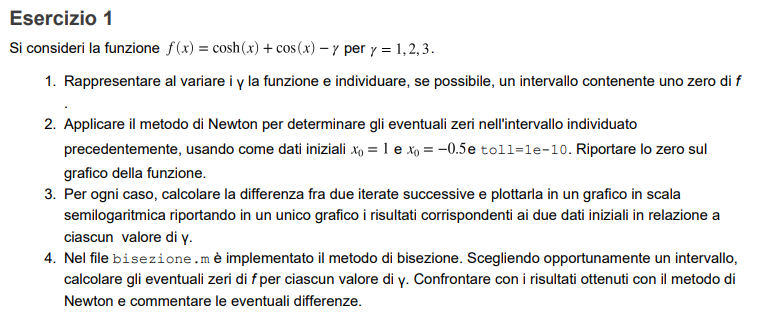

% clear all
% close all
% 
% for gamma = 1:1:3
%     f = @(x) cosh(x)+cos(x)-gamma;
%     figure
%     fplot(f,[-2 2])
%     grid on
% end

per gamma = 1 non ci sono zeri

per gamma = 2 c'è uno zero

per gamma = 3 ci ono due zero

clear all
close all

syms x
toll = 1e-10;
Nmax = 100;
x0 = [1 -0.5]

x0 =     1.0000   -0.5000


f = function_handle with value:
    @(x)cos(x)+cosh(x)-1.0

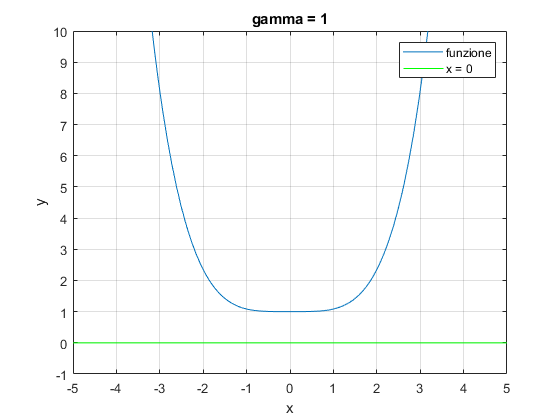

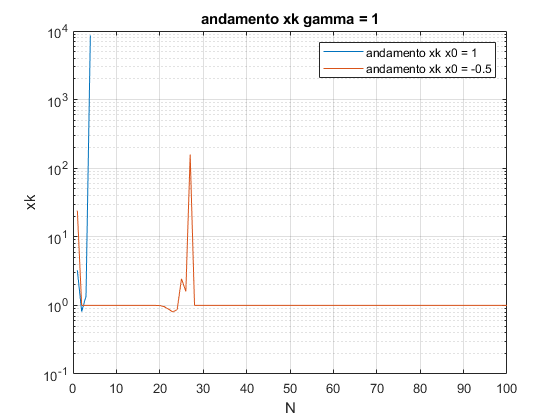

f = function_handle with value:
    @(x)cos(x)+cosh(x)-2.0

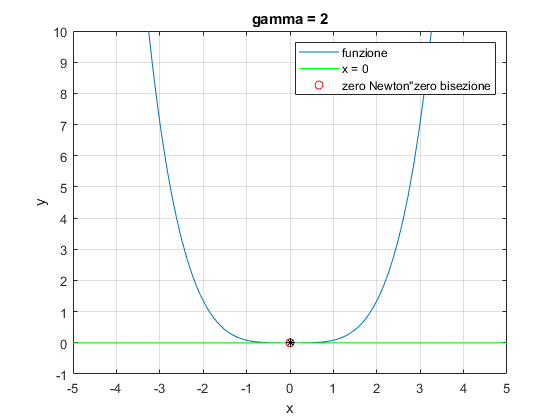

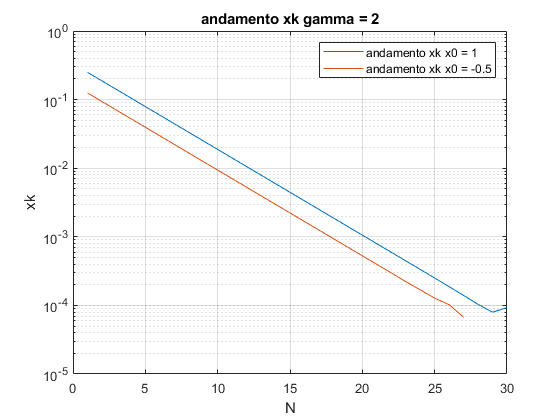

f = function_handle with value:
    @(x)cos(x)+cosh(x)-3.0

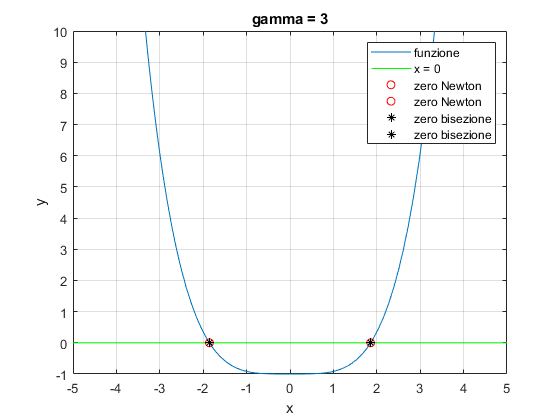

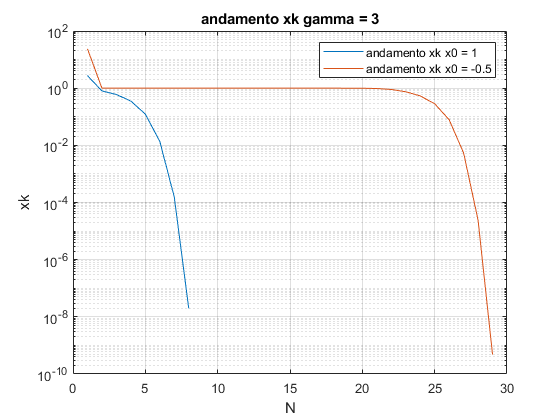


for gamma = 1:1:3
    f = cosh(x)+cos(x)-gamma;
    figure
    fplot(f)
    grid on
    hold on
    plot([-10,10],[0 0],'g')
    ylim([-1 10])
    xlim([-5 5])
    
    [zero,fz,iter,xk] = newton(f,x0(1),toll,Nmax);
    diff1 = abs(xk(1:end-1)-xk(2:end));
    if(fz<=toll)
        plot(zero,fz,'or')
    end
    
    [zero,fz,iter,xk] = newton(f,x0(2),toll,Nmax);
    diff2= abs(xk(1:end-1)-xk(2:end));
    if(fz<=toll)
        plot(zero,fz,'or')
    end
    f = matlabFunction(f)
    [zero,fval,iter] = bisezione(f,-2,0,toll);
    if(fval<=toll)
        plot(zero,fz,'*k')
    end
    
    [zero,fval,iter] = bisezione(f,0,2,toll);
    if(fval<=toll)
        plot(zero,fz,'*k')
    end
    title("gamma = "+ gamma) 
    xlabel x
    ylabel y
    if gamma == 1
        legend("funzione","x = 0")
    elseif gamma == 2
        legend("funzione","x = 0","zero Newton""zero bisezione")
    else
       legend("funzione","x = 0","zero Newton","zero Newton", ...
           "zero bisezione","zero bisezione")
    end
    
    figure
    semilogy(diff1)
    hold on
    semilogy(diff2)
    legend("andamento xk x0 = 1","andamento xk x0 = -0.5")
    title("andamento xk gamma = "+gamma)
    xlabel N
    ylabel xk
    hold off
    grid on
end

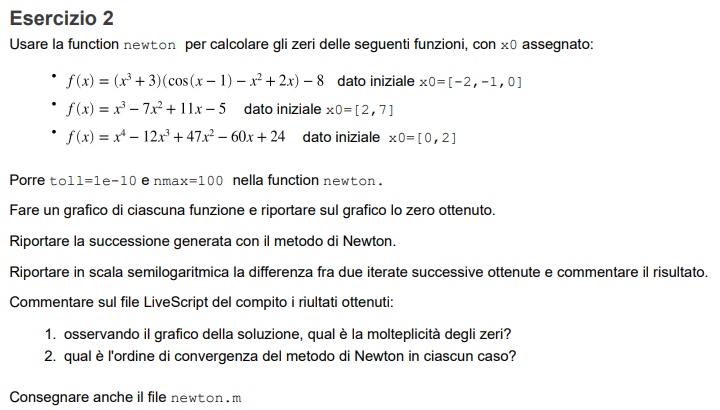

clear all
close all

syms x
toll = 1e-10;
Nmax = 100;

f = (x.^3+3).*(cos(x-1)-x.^2+2*x)-8;
figure(2)
fplot(f)
grid on
hold on
plot([-10,10],[0 0],'g')
ylim([-10 10])
xlim([-3 3])
X0 = [-2 -1 0];
for x0 = X0
    [zero,fz,iter,xk] = newton(f,x0,toll,Nmax);
    figure(10)
    plot(xk)
    hold on 
    diff1 = abs(xk(1:end-1)-xk(2:end));
    if(fz<=1)
        figure(2)
        plot(zero,fz,'or')
    end
    ordineConv(matlabFunction(diff(f)),x0,zero)
    figure(3)
    semilogy(diff1)
    hold on
end

per x0=-2 si ha uno zero singolo
ordine di convergenza 2


per x0=-1 si ha uno zero singolo
ordine di convergenza 2


per x0=0 si ha uno zero singolo
ordine di convergenza 2


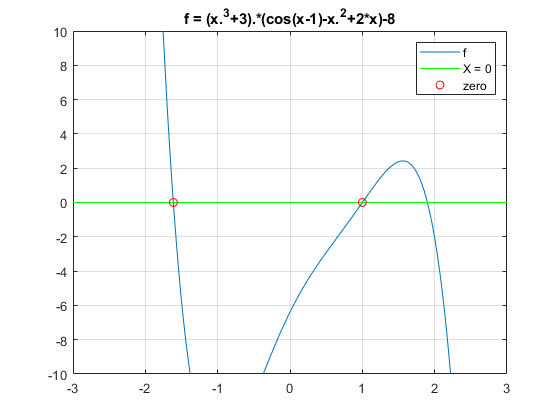

figure(2)
title("f = (x.^3+3).*(cos(x-1)-x.^2+2*x)-8")
legend("f","X = 0","zero")

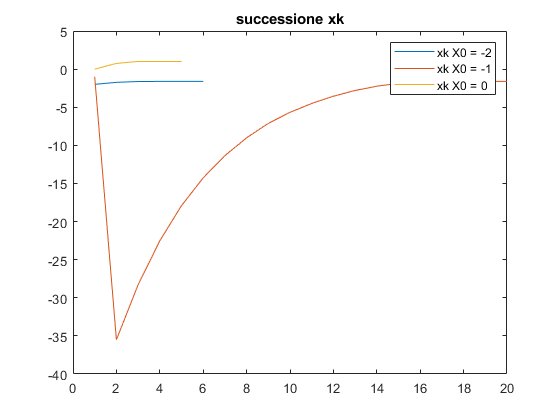

figure(10)
title("successione xk")
legend("xk X0 = -2","xk X0 = -1","xk X0 = 0")

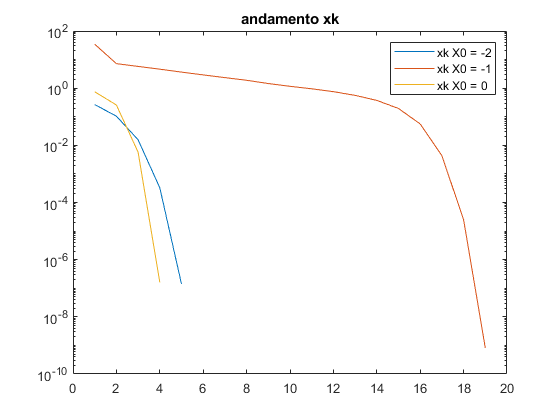

figure(3)
title("andamento xk")
legend("xk X0 = -2","xk X0 = -1","xk X0 = 0")



disp("si trovano due zeri di cui quello in x =-1.xx con moltepilciità 2 " + ...
    "mentre quello in x =1.xx con molteplicità 1, con i valoi di partenza " + ...
    "non si riece a trovare il terzo zero in x=2 se si pone x0 = 3 si potrebbe trovare anche lui")

si trovano due zeri di cui quello in x =-1.xx con moltepilciità 2 mentre quello in x =1.xx con molteplicità 1, con i valoi di partenza non si riece a trovare il terzo zero in x=2 se si pone x0 = 3 si potrebbe trovare anche lui



f = x.^3 -7*x.^2 +11*x -5;
figure(4)
fplot(f)
grid on
hold on
plot([-10,10],[0 0],'g')
ylim([-10 10])
xlim([-2 8])
X0 = [7 2];
for x0 = X0
    [zero,fz,iter,xk] = newton(f,x0,toll,Nmax);
    figure(11)
    plot(xk)
    hold on
    diff1 = abs(xk(1:end-1)-xk(2:end));
    if(fz<=1)
        figure(4)
        plot(zero,fz,'or')
    end
    ordineConv(matlabFunction(diff(f)),x0,zero)
    figure(5)
    semilogy(diff1)
    hold on
end

per x0=7 si ha uno zero singolo
ordine di convergenza 2


per x0=2 si ha uno zero doppio
ordine di convergenza 1


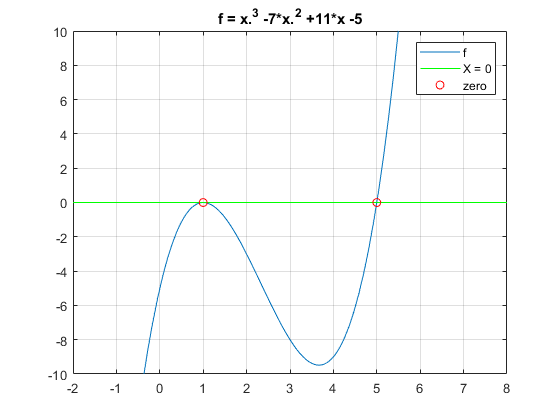

figure(4)
title("f = x.^3 -7*x.^2 +11*x -5")
legend("f","X = 0","zero")

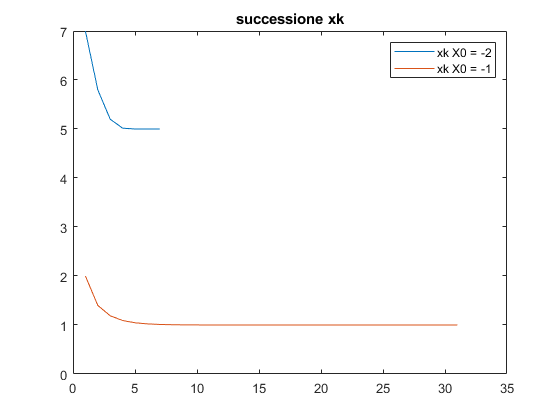

figure(11)
title("successione xk")
legend("xk X0 = -2","xk X0 = -1","xk X0 = 0")

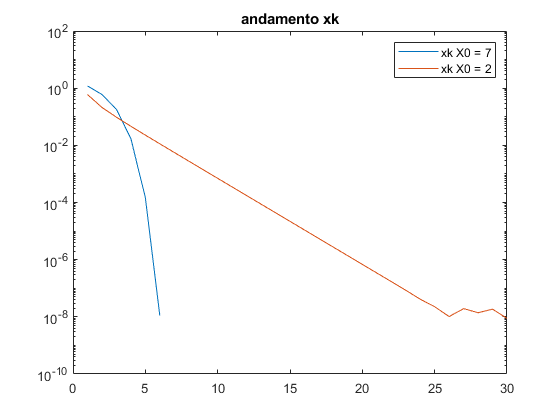

figure(5)
title("andamento xk")
legend("xk X0 = 7","xk X0 = 2")


f = x.^4-12*x.^3+47*x.^2-60*x+24;
figure(6)
fplot(f)
grid on
hold on
plot([-10,10],[0 0],'g')
ylim([-0.5 1])
xlim([0 2])
X0=[0 2];
for x0 = X0
    [zero,fz,iter,xk] = newton(f,x0,toll,Nmax);
    figure(12)
    plot(xk)
    hold on
    diff1 = abs(xk(1:end-1)-xk(2:end));
    if(fz<=1)
        figure(6)
        plot(zero,fz,'or')
    end
    ordineConv(matlabFunction(diff(f)),x0,zero)
    figure(7)
    semilogy(diff1)
    hold on
end

per x0=0 si ha uno zero singolo
ordine di convergenza 2


per x0=2 si ha uno zero singolo
ordine di convergenza 2


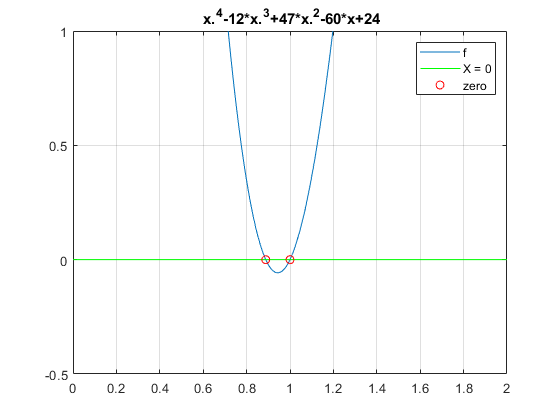

figure(6)
title(" x.^4-12*x.^3+47*x.^2-60*x+24")
legend("f","X = 0","zero")

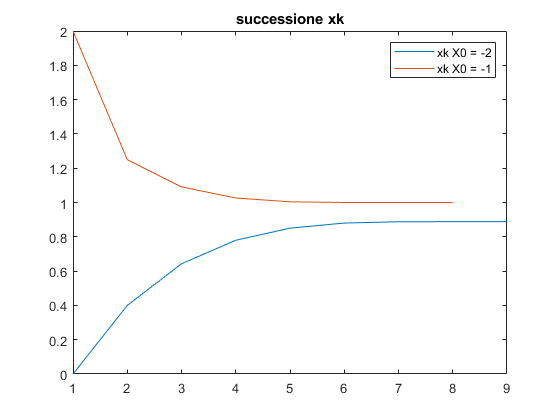

figure(12)
title("successione xk")
legend("xk X0 = -2","xk X0 = -1","xk X0 = 0")

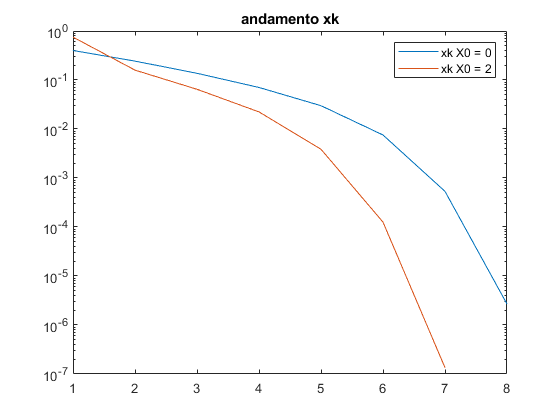

figure(7)
title("andamento xk")
legend("xk X0 = 0","xk X0 = 2")

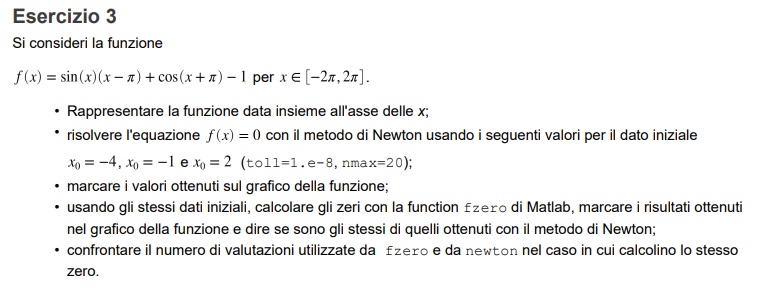

clear all
close all
syms x
f = sin(x).*(x-pi)+cos(x+pi)-1;
figure(9)
fplot(f)
grid on
hold on
plot([-10,10],[0 0],'g')
%ylim([-0.5 1])
xlim([-2*pi 2*pi])
X0=[-4 -1 2];
toll=1.e-8;
Nmax = 20;
for x0 = X0
    [zero,fz,iter,xk] = newton(f,x0,toll,Nmax);
    disp("iterNewton = " +iter)
    figure(20)
    plot(zero,iter,'xb')
    hold on
    diff1 = abs(xk(1:end-1)-xk(2:end));
    if(fz<=1)
        figure(9)
        plot(zero,fz,'or')
        hold on
    end
    %ordineConv(matlabFunction(diff(f)),x0,zero)
    figure(10)
    semilogy(diff1)
    hold on
    [zero,fz,flag,output] = fzero(matlabFunction(f),x0);
    iterfzero = output.iterations + output.intervaliterations
    
    figure(20)
    plot(zero,iter,'xr')
    hold on
    
    figure(9)
    plot(zero,fz,'*k')
    hold on
end

iterNewton = 4


iterfzero = 12

iterNewton = 3


iterfzero = 16

iterNewton = 20


iterfzero = 18

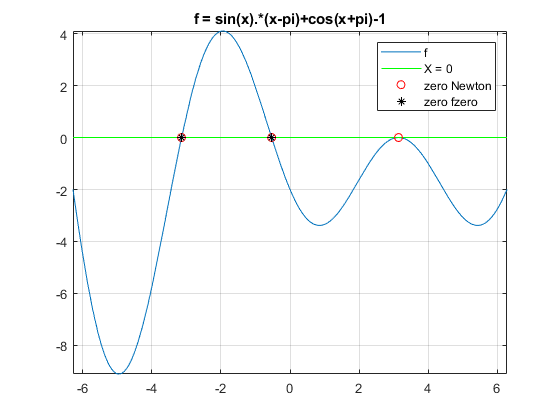


figure(9)
title("f = sin(x).*(x-pi)+cos(x+pi)-1")
legend("f","X = 0","zero Newton","zero fzero")

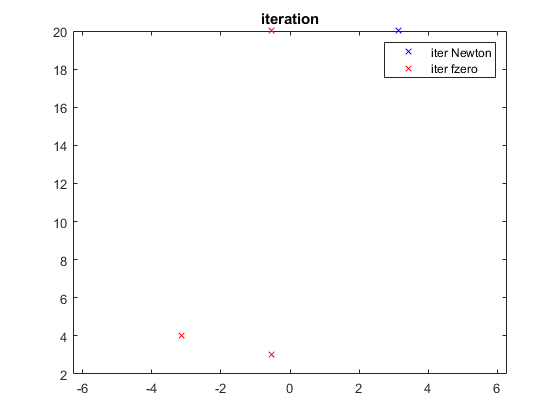

figure(20)
title("iteration")
legend("iter Newton","iter fzero")
xlim([-2*pi 2*pi])

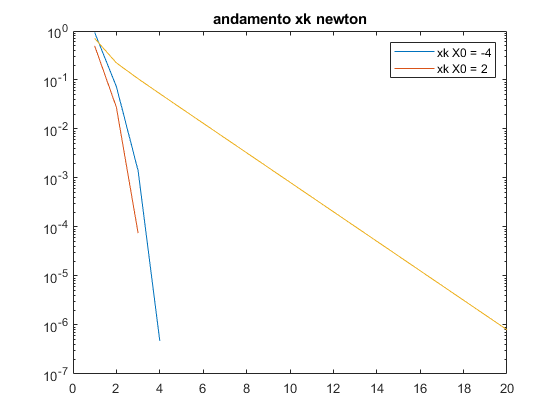

figure(10)
title("andamento xk newton")
legend("xk X0 = -4","xk X0 = 2")

Come si vede il metodo di Newton arriva a risultato in un numero inferiore di iterazioni rispetto alla funzione fzero di Matlab, questo può essere giustificato dal fatto che le condizioni di convergenza della funzione fzero sono meno stringenti.